## Travelling Salesman Problem

The TSP is the following: 

"Given a list of cities and the distances between each pair of cities, what is the shortest possible route that visits each city and returns to the origin city?". [[Wikipedia](https://en.wikipedia.org/wiki/Travelling_salesman_problem)]

This is an optimization (minimization) problem, where the objective function is the total length of the route.

### Definitions

The cities are defined with their x and y coordinates.


$$\left[\begin{array}{cc} x_{1} & y_{1}\\ x_{2} & y_{2}\\ \vdots & \vdots\\ x_{n} & y_{n} \end{array}\right]$$


where *n *is the number of cities.

The matrix of distances **A** is a matrix where each element $a_{ij}$ represent the distance between the i-th and j-th cities.


$$A=\left[\begin{array}{cccc}
0 & a_{12} & \dots & a_{1n}\\
a_{21} & 0 & \dots & a_{2n}\\
\vdots & \vdots & \ddots & \vdots\\
a_{n1} & a_{n2} & \dots & 0
\end{array}\right]$$


where $a_{ij}=a_{ji}=||x_{i}-x_{j}||$. Two properties of this matrix are:

- it is a square matrix;

- it is symmetric;

- the element on the diagonal are zeros.

### Simulation

Random cities are initialized.

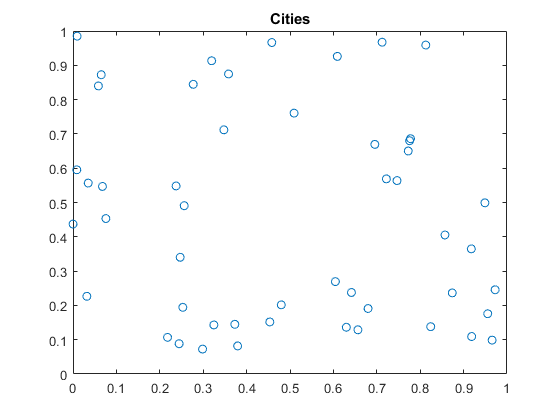

nCities = 50;       % number of cities
seed = 13;                  % random seed
rng(seed);
cities = rand(nCities, 2);        % x and y coordinates of cities
figure();
plot(cities(:, 1), cities(:, 2), 'o')
title('Cities')

% Matrix of diastances: A_ij is the distance from i-th city to j-th.
% A is symmetric
A = zeros(nCities, nCities);            
for i = 1:nCities
    for j = 1:i
        A(i, j) = norm(cities(i,:)-cities(j,:));
        A(j, i) = A(i, j);
    end
end

data.depot = 1;
data.distanceMatrix = A;
data.cities = cities;


### Optimization algorithm

The TSP is a NP-hard combinatory problem; a robust solver is therefore needed. In this case, the** simulated annealing** algorithm has been used. This works as follows:

- Start with an initial random solution, which has a value $f\left(x_0 \right)$ of the objective function. By now, this is the best solution.

- Select a local neighbor of this solution and compute $f\left(x_{\mathrm{new}} \right)$. The local neighbor is created with an inversion of a sub-route of the total route.

- If $\Delta E=\left(x_{\mathrm{new}} \right)-f\left(x_{\mathrm{best}} \right)\le 0$, then the new solution is accepted: $x_{\mathrm{best}} =x_{\mathrm{new}}$.

- If $\Delta E>0$, the solution could still be accepted. This happens with a probability $P\left(\Delta E\right)=e^{-\frac{\Delta E}{\mathrm{kT}}}$. The *temperature ***T **is a fundamental variable of the algorithm. As the number of iterations grows, the temperature decrease (with a geometric progression: $T\left(i\right)=T\left(i-1\right)\cdot \mathrm{cr}$, where $\mathrm{cr}$ is the cooling ratio). So, the greater the iteration number, the less probability there is to accept a solution which does not optimize the objective function.

- Repeat 2-4 until convergence.

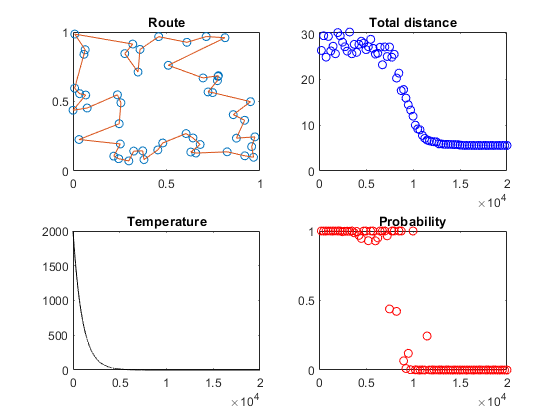

 
[xMin]=SimulatedAnnealing(@ComputeDistance, 2:nCities, data, 20000, 2000, 1, 0.999, 1e-3);

function totalDistance = ComputeDistance(route, data)
    depot = data.depot;
    distanceMatrix = data.distanceMatrix;
    cities = data.cities;
    totalDistance = 0;
    completeRoute = [depot route depot];
    
    for i = 1:size(completeRoute, 2)-1
        totalDistance = totalDistance + distanceMatrix(completeRoute(i), completeRoute(i+1));
    end
end

function [bestX] = SimulatedAnnealing(fun, x0, args, maxIter, T0, k, cr, tol)
    bestX = x0;
    T = [T0];
    for nIter = 1:maxIter
        newX = bestX;
        
        idx1 = randi(size(newX, 2));
        idx2 = randi(size(newX, 2));
        
        if idx1 < idx2
            newX(idx1:idx2) = bestX(idx2:-1:idx1);
        elseif idx1 > idx2
            newX(idx2:idx1) = bestX(idx1:-1:idx2);
        end
        deltaE = fun(newX, args) - fun(bestX, args);
        
        if deltaE <= 0
            bestX = newX;
            probability = 1;
        else
            probability = exp(-deltaE/(T(end)*k));
            if probability > rand()
                bestX = newX;
            end
            if (deltaE <= tol & exp(T(end)) <= tol)
                display('Convergence reached at iteration ' + string(nIter));
                break
            end
        end
            T = [T, T(end) * cr];
        completeRoute = [args.depot bestX args.depot];
        if rem(nIter,250) == 0
            % Routes plot
            subplot(221)
            plot(args.cities(:,1), args.cities(:,2), 'o')
            title('Route')
            hold on;
            plot(args.cities(completeRoute, 1), args.cities(completeRoute, 2))
            drawnow;
            hold off;
            
            % Objective function
            subplot(222)
            plot(nIter, fun(bestX, args), 'bo')
            title('Total distance')
            hold on;
            
            % Simulated annealing temperature
            subplot(223)
            plot(T, 'k')
            title('Temperature')
            
            % Probability of acceptance
            subplot(224)
            plot(nIter, probability, 'ro')
            title('Probability')
            hold on;
        end
            
    end
    hold off
end